# **FEM2D: Thermal Problem Using Linear Triangular Elements**

Consider the thermal boundary value problem,


$$-\frac{\partial^{2} u}{\partial x^{2}}- \frac{\partial^{2} u}{\partial y^{2}} = 0,\quad (x,y)\in \Omega = [-1,1]^{2}\setminus B^{2}_{1/2}(0,0),$$


with boundary conditions:


$$\begin{array}{lc}
u(x,-1) = u(x,1) = 10, &\ -1\le x\le 1,\\
u_{x}(-1,y) = u_{x}(1,y) = 0, &\ -1\le y\le 1,\\
u(x,y) = 50, &\ \ (x,y) \in\partial B^{2}_ {1/2}(0,0).
\end{array}$$


As shown in the figure,

                                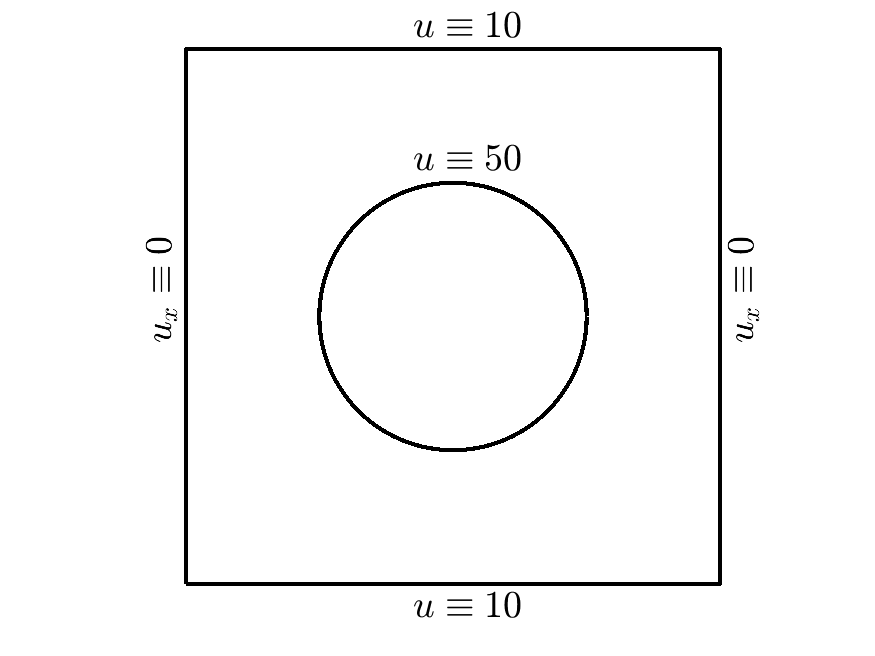

Use the FEM with the mesh given in the file `CircleHolemesh01.m` to find the temperature distribution on $\Omega$.

clearvars
close all

a11 = 1.0;
a12 = 0.0;
a21 = a12;
a22 = a11;
a00 = 0.0;
f   = 0.0;

tempCirc = 50.0;
tempTop = 10.0;
tempBot = tempTop;

p=[0.5, 0.8];

%eval('CircleHolemesh01');
load CircleHolemesh01 %Load the nodes and the connectivity matrix from a .mat file

numNod = size(nodes,1);
numElem = size(elem,1);

numbering = 0;
plotElements(nodes, elem, numbering);
hold on

Let's pick the nodes at the top, at the bottom and at the circle

nodesTop = find(nodes(:,2) > 0.99);
nodesBot = find(nodes(:,2) < -0.99);
nodesCirc = find(sqrt(nodes(:,1).^2 + nodes(:,2).^2)< 0.501);

And plot the selected nodes...

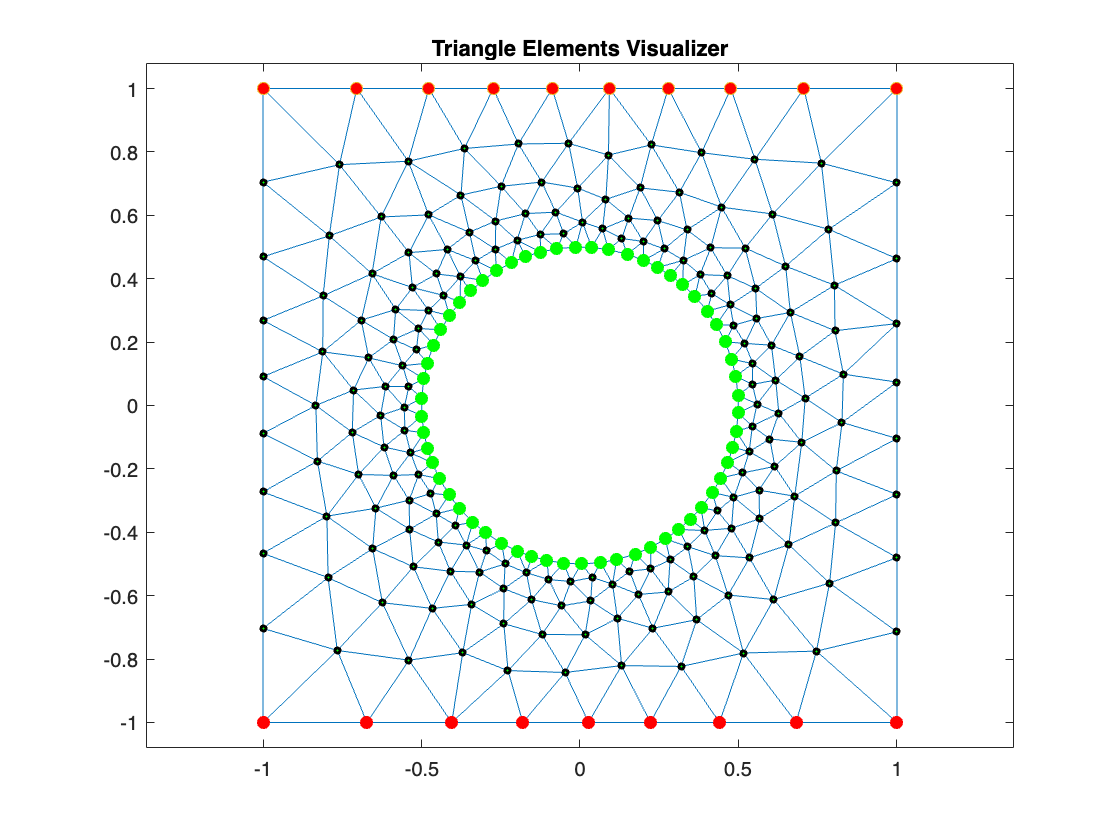

plot(nodes(nodesTop,1),nodes(nodesTop,2),'o','markerFaceColor','red')
plot(nodes(nodesBot,1),nodes(nodesBot,2),'o','markerFaceColor','red','Color','red')
plot(nodes(nodesCirc,1),nodes(nodesCirc,2),'o','markerFaceColor','green','Color','green')
hold off

coeff=[a11,a12,a21,a22,a00,f];
K = zeros(numNod);
F = zeros(numNod,1);
Q = zeros(numNod,1);

for e=1:numElem
    [Ke, Fe] = linearTriangElement(coeff,nodes,elem,e);
    rows =[elem(e,1),elem(e,2),elem(e,3)];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end

**Boundary conditions**

fixedNodes = [nodesTop',nodesBot',nodesCirc'];
freeNodes = setdiff(1:numNod,fixedNodes);

Natural B.C:

Q(freeNodes)=0.0; % !all them are zero

Essential B.C.

u = zeros(numNod,1);
u(nodesTop) = tempTop;
u(nodesBot) = tempBot;
u(nodesCirc) = tempCirc;

Reduced system

Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

Solve the reduced system

um = Km\Im;
u(freeNodes) = um;

Post process: computation of $$Q$$'s, tabular, and plot.

Q = K*u-F;

table.Nod = int64((1:numNod)');
table.X = nodes(:,1);
table.Y = nodes(:,2);
table.U = u;
table.Q = Q;

format short e
tableTemp=struct2table(table)

tableTemp = 260×5 table
    Nod         X              Y             U              Q     
    ___    ___________    ___________    __________    ___________

     1     -1.0000e+00    -1.0000e+00    1.0000e+01    -7.5917e+00
     2     -1.0000e+00     1.0000e+00    1.0000e+01    -6.8104e+00
     3      1.0000e+00    -1.0000e+00    1.0000e+01    -7.3521e+00
     4      1.0000e+00     1.0000e+00    1.0000e+01    -6.7716e+00
     5     -1.0000e+00    -4.6643e-01    3.2202e+01    -3.5527e-15
     6     -1.0000e+00    -2.7277e-01    3.7333e+01     2.1316e-14
     7     -1.0000e+00    -8.7995e-02    3.9858e+01     7.1054e-15
     8     -1.0000e+00     9.1708e-02    3.9822e+01     1.7764e-14
     9     -1.0000e+00     2.6827e-01    3.7417e+01     3.5527e-15
    10     -1.0000e+00     4.6904e-01    3.2133e+01    -1.7764e-15
 

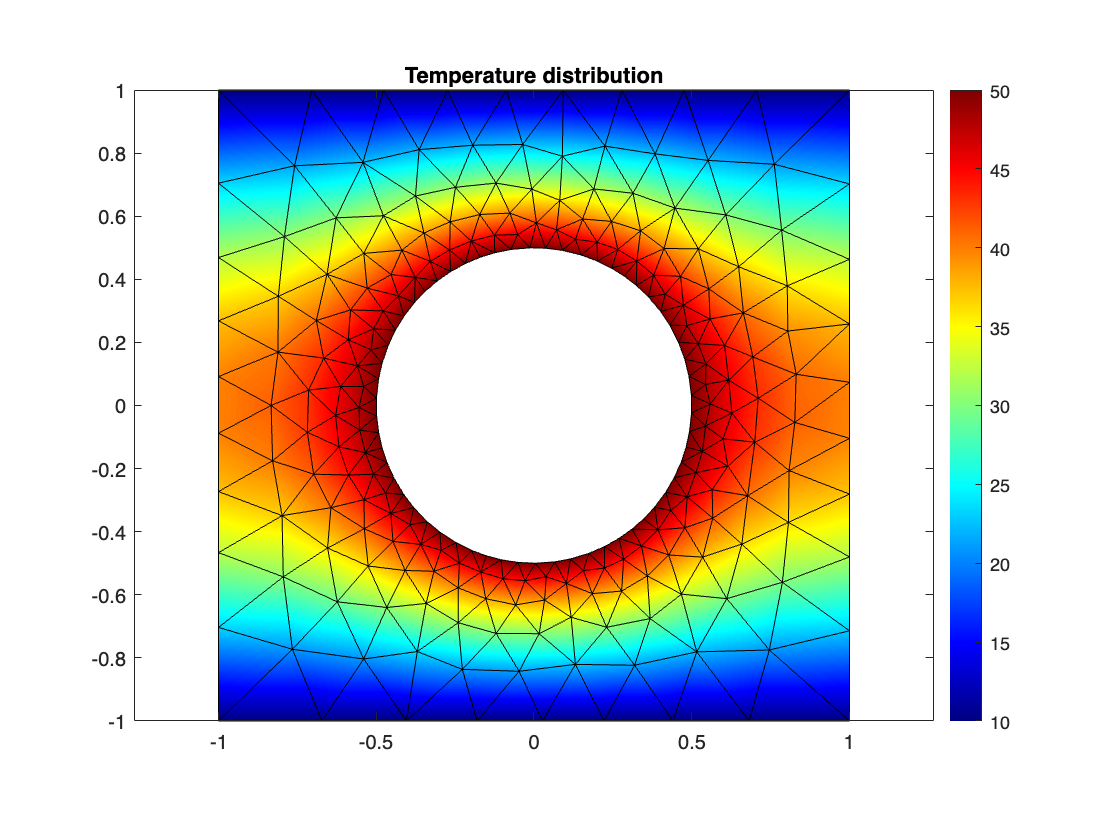


title='Temperature distribution';
colorMap = 'jet';
plotContourSolution(nodes,elem,u,title,colorMap)

## Exercise 1:

Compute the temperature for the point **p=[0.5, 0.8]**.

for e = 1:numElem
    v1 = nodes(elem(e,1),:);
    v2 = nodes(elem(e,2),:);
    v3 = nodes(elem(e,3),:);
    vertexs = [v1;v2;v3];
    [alphas, isInside] = baryCoord(vertexs, p);
    if isInside >= 1
        numElemP = e;
        numNodsP = elem(numElemP,:);
        interpTempAtP = alphas * u(numNodsP);
        break;
    end
end

% fmt = ['\nSolution Ex.1: Interpolated temp.\n', ...
%        'Point p = (%.2f,%.2f)\n',...   
%        'Element Num: %4d\n',...
%        'Nodes: %d, %d, %d\n', ...
%        'Temp.: %12.5e%cC\n'
%       ];
fmt = [
 ' ====================== Exercise 1 =========================\n',...
 ' Point P = (%.1f,%.1f) belongs to element number: %d\n',...
 ' Number of nodes of elem %d: %d, %d, %d\n',...
 ' Interpolated temperature at point P: %.4e%cC\n',...
 ' ===========================================================\n'
 ];  
fprintf(fmt,p,numElemP,numElemP,numNodsP,interpTempAtP,char(176))

 ====================== Exercise 1 =========================
 Point P = (0.5,0.8) belongs to element number: 206
 Number of nodes of elem 206: 172, 221, 177
 Interpolated temperature at point P: 2.1258e+01°C
